# SCR grand average for Study 2 data

Stimulus-locked grand average. For each trial, a baseline was created by averaging physiological time-series data from 3 seconds before the thermal stimulation onset.  A stimulus-locked physiological response was generated by subtracting the baseline value from the data in the 20-second period after the stimulation onset. 

## 1. Checking the data

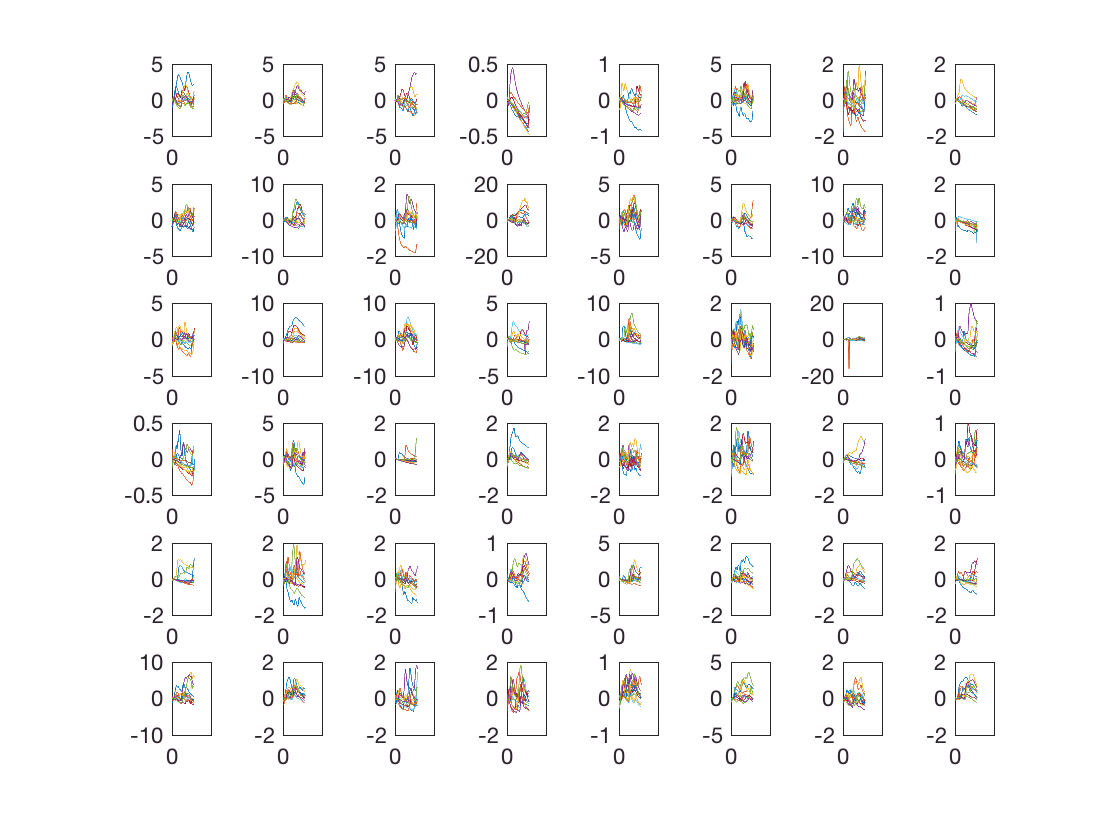

close all;
clear;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../marianne_data/CT_SCR_TempSort_Wani.mat');

% first 6 columns are 47 degrees
% next 3 are 48
% the last 3 are 49

% Sanity check
figure;
for i = 1:numel(Main_Present_SCR)
    subplot(6,8,i)
    plot(Main_Present_SCR{i})
end

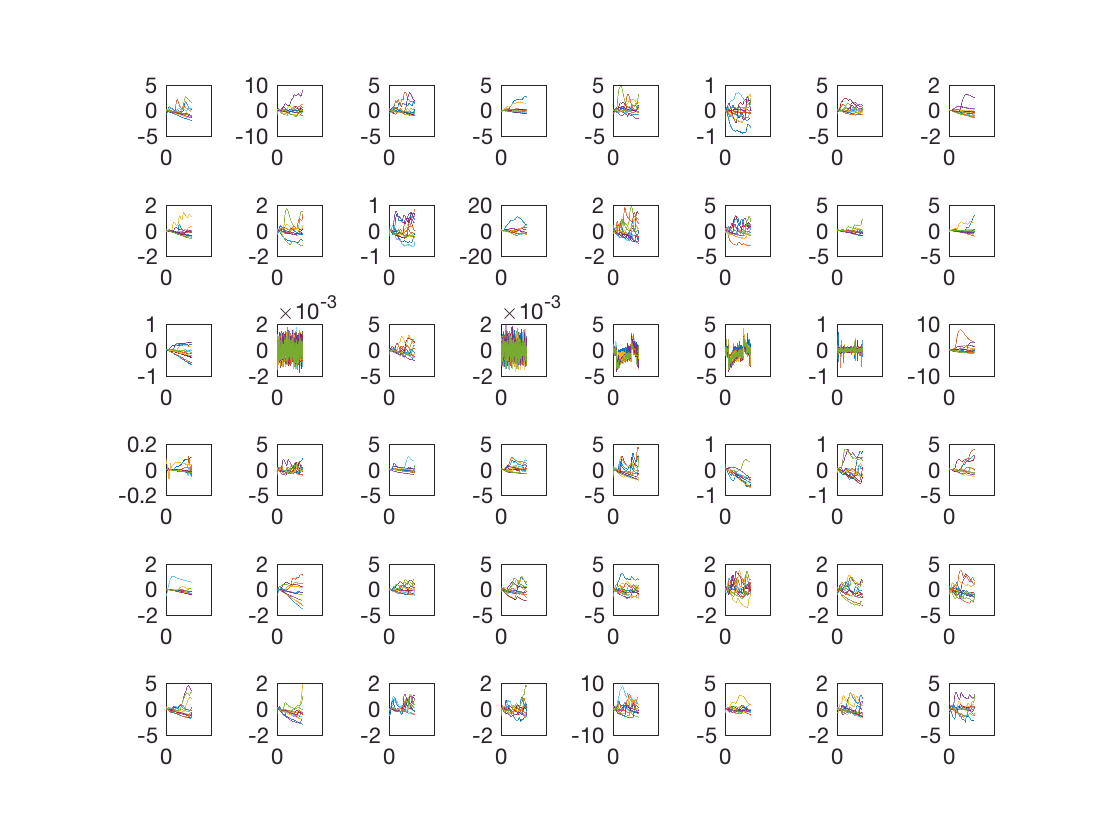


% remove big drop (outlier)
Main_Present_SCR{23}(:,9) = NaN(575,1);

figure;
for i = 1:numel(Main_Present_SCR)
    subplot(6,8,i)
    plot(Part_Present_SCR{i})
end

## 2. Data cleaning and formatting


%% There are subjects with tech errors
bad_subjects = [119,122,123,124,126,127,134];
bad_subj_idx = find(ismember(cat(2,CT_Subs{:,1}), bad_subjects));
good_subj_idx = find(~ismember(cat(2,CT_Subs{:,1}), bad_subjects));

% Get average signal for each temp 
clear signal_m;
k = 0;
for i = 1:numel(Main_Present_SCR)
    
%     signal_m.main{1}(i,:) = nanmean(Main_Present_SCR{i}(:,1:6),2)';
%     signal_m.main{2}(i,:) = nanmean(Main_Present_SCR{i}(:,7:9),2)';
%     signal_m.main{3}(i,:) = nanmean(Main_Present_SCR{i}(:,10:12),2)';

    if ~any(ismember(bad_subjects, CT_Subs{i,1}))
        k = k + 1;
        
        signal_m.main{1}(k,:) = nanmean(Main_Present_SCR{i}(:,1:6),2)';
        signal_m.main{2}(k,:) = nanmean(Main_Present_SCR{i}(:,7:9),2)';
        signal_m.main{3}(k,:) = nanmean(Main_Present_SCR{i}(:,10:12),2)';
        
        signal_m.partner{1}(k,:) = nanmean(Part_Present_SCR{i}(:,1:6),2)';
        signal_m.partner{2}(k,:) = nanmean(Part_Present_SCR{i}(:,7:9),2)';
        signal_m.partner{3}(k,:) = nanmean(Part_Present_SCR{i}(:,10:12),2)';
    end
end

## 3. All temperature (Main); SCR grand average

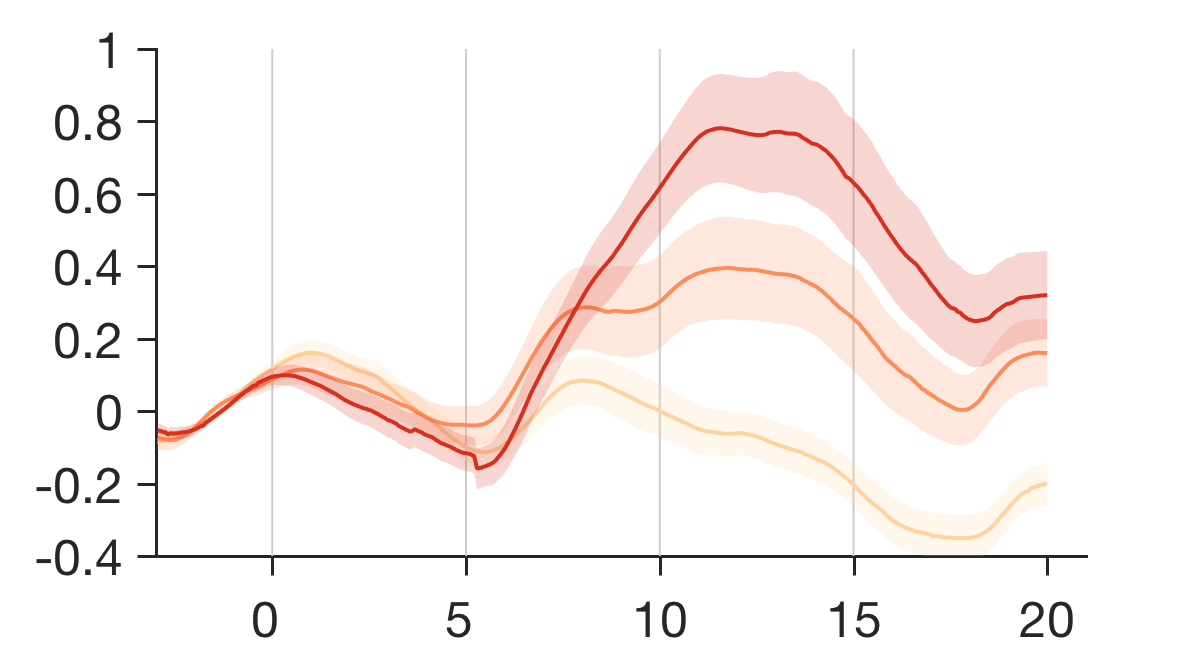

close all;
figdir = '../figures';

x = 1:575;
create_figure('shading');
cols = [0.9922    0.8314    0.6196
    0.9882    0.5529    0.3490
    0.8431    0.1882    0.1216];

for i = (3:5:21)*25
    line([i i], [-.5 1.05], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:3
    hold on;
    wani_plot_shading(x, mean(signal_m.main{i}), ste(signal_m.main{i}), 'color', cols(i,:), 'alpha', .2);
    % line([615 660], repmat(median(mean(signal_m.main{i},2)), 1, 2), 'color', cols(i,:), 'linewidth', 3)
    % [~,idx.main{i}] = max(signal_m.main{i}(:,76:575)');
    % scatter([idx.main{i}'+75], ones(numel(idx.main{i}),1)+i./40-.05, 20, cols(i,:), 'filled')
end

set(gcf, 'position', [50   126   600   324]);
set(gca, 'xlim', [0 600], 'ylim', [-.4 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:25)*25, 'ytick', -.4:.2:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);

savename = fullfile(figdir, 'Study2_Temp_all_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## 4. All temperature (Partner); SCR grand average

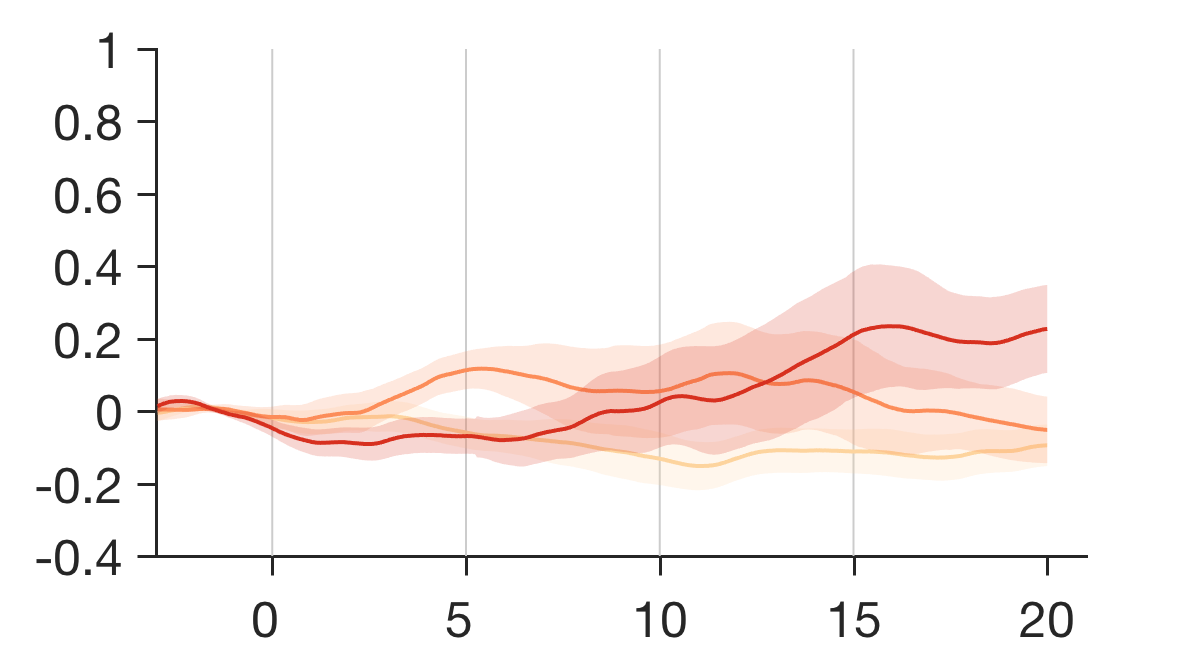

close all;
figdir = '../figures';

x = 1:575;
create_figure('shading');

for i = (3:5:21)*25
    line([i i], [-.5 1.05], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:3
    hold on;
    wani_plot_shading(x, mean(signal_m.partner{i}), ste(signal_m.main{i}), 'color', cols(i,:), 'alpha', .2);
    % line([615 660], repmat(median(mean(signal_m.partner{i},2)), 1, 2), 'color', cols(i,:), 'linewidth', 3)
    % [~,idx.partner{i}] = max(signal_m.partner{i}(:,76:575)');
    % scatter([idx.partner{i}'+75], ones(numel(idx.partner{i}),1)+i./40-.05, 20, cols(i,:), 'filled')
end

set(gcf, 'position', [50   126   600   324]);
set(gca, 'xlim', [0 600], 'ylim', [-.4 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:25)*25, 'ytick', -.4:.2:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);

savename = fullfile(figdir, 'Study2_partner_Temp_all_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## stats

clear xx y*;
y_main_max = cellfun(@(x) max(x(:,76:575)')', signal_m.main, 'Uniformoutput', false);
y_partner_max = cellfun(@(x) max(x(:,76:575)')', signal_m.partner, 'Uniformoutput', false);

y_main_sum = cellfun(@(x) mean(x,2), signal_m.main, 'Uniformoutput', false);
y_partner_sum = cellfun(@(x) mean(x,2), signal_m.partner, 'Uniformoutput', false);


## glm main max

clear glm_x*;
for i = 1:numel(y_main_max{3})
    glm_y_main_max{i} = [y_main_max{1}(i);y_main_max{2}(i);y_main_max{3}(i)];
    glm_x_49_47{i} = [-1;0;1];
    glm_x_49_48{i} = [0;-1;1];
    glm_x_48_47{i} = [-1;1;0];
end

glmstats.main_max{1} = glmfit_multilevel(glm_y_main_max, glm_x_49_47, [], 'noverbose','boot', 'nresample', 10000);
glmstats.main_max{2} = glmfit_multilevel(glm_y_main_max, glm_x_49_48, [], 'noverbose','boot', 'nresample', 10000);
glmstats.main_max{3} = glmfit_multilevel(glm_y_main_max, glm_x_48_47, [], 'noverbose','boot', 'nresample', 10000);

contrasts = {'49 vs. 47', '49 vs. 48', '48 vs. 47'};
glmresults =  glmstats.main_max;
for i = 1:3
    fprintf('\nfor %s, beta = %.3f +- %.3f, z = %.3f, p = %.4f', contrasts{i}, glmresults{i}.beta(2), glmresults{i}.ste(2), glmresults{i}.z(2), glmresults{i}.p(2))
end


for 49 vs. 47, beta = 0.343 +- 0.076, z = 4.961, p = 0.0000


for 49 vs. 48, beta = 0.159 +- 0.079, z = 2.847, p = 0.0044


for 48 vs. 47, beta = 0.183 +- 0.072, z = 5.767, p = 0.0000

## Partner max


clear glm_x*;

for i = 1:numel(y_partner_max{3})
    glm_y_patner_max{i} = [y_partner_max{1}(i);y_partner_max{2}(i);y_partner_max{3}(i)];
    glm_x_49_47{i} = [-1;0;1];
    glm_x_49_48{i} = [0;-1;1];
    glm_x_48_47{i} = [-1;1;0];
end

glmstats.partner_max{1} = glmfit_multilevel(glm_y_partner_max, glm_x_49_47, [],'noverbose','boot', 'nresample', 10000);
glmstats.partner_max{2} = glmfit_multilevel(glm_y_partner_max, glm_x_49_48, [], 'noverbose','boot', 'nresample', 10000);
glmstats.partner_max{3} = glmfit_multilevel(glm_y_partner_max, glm_x_48_47, [], 'noverbose','boot', 'nresample', 10000);

contrasts = {'49 vs. 47', '49 vs. 48', '48 vs. 47'};
glmresults =  glmstats.partner_max;
for i = 1:3
    fprintf('\nfor %s, beta = %.3f +- %.3f, z = %.3f, p = %.4f', contrasts{i}, glmresults{i}.beta(2), glmresults{i}.ste(2), glmresults{i}.z(2), glmresults{i}.p(2))
end


for 49 vs. 47, beta = 0.193 +- 0.049, z = 4.765, p = 0.0000


for 49 vs. 48, beta = 0.041 +- 0.082, z = 0.512, p = 0.6084


for 48 vs. 47, beta = 0.152 +- 0.053, z = 3.827, p = 0.0001

## Main vs Partner

for i = 1:numel(y_partner_max{3})
    glm_y_main_vs_patner_max{i} = [y_main_max{1}(i);y_main_max{2}(i);y_main_max{3}(i);y_partner_max{1}(i);y_partner_max{2}(i);y_partner_max{3}(i)];
    glm_x_main_vs_partner{i} = [1;1;1;-1;-1;-1];
end

glmstats.main_vs_partner_max{1} = glmfit_multilevel(glm_y_main_vs_patner_max, glm_x_main_vs_partner, [],'noverbose','boot', 'nresample', 10000);
glmresults = glmstats.main_vs_partner_max; 
i=1;
fprintf('\nfor main vs. partner, beta = %.3f +- %.3f, z = %.3f, p = %.4f', glmresults{i}.beta(2), glmresults{i}.ste(2), glmresults{i}.z(2), glmresults{i}.p(2))


for main vs. partner, beta = 0.145 +- 0.060, z = 2.778, p = 0.0055

## Plot

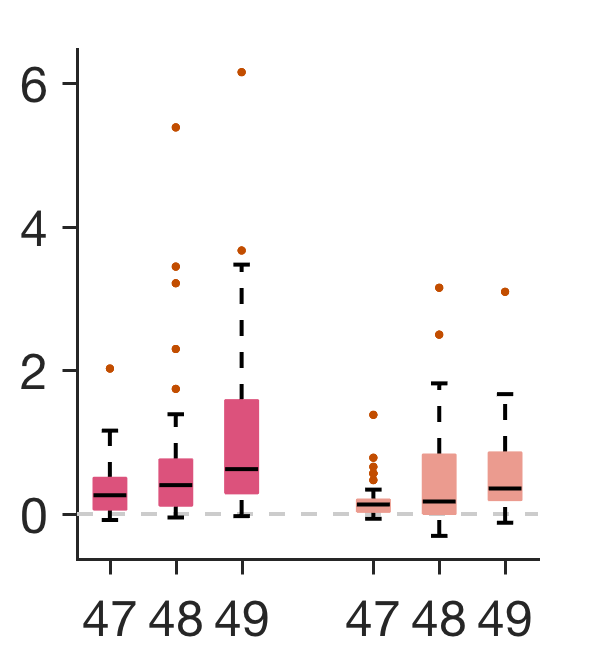

data = [cat(2,y_main_max{:}) NaN(42,1) [cat(2,y_partner_max{:})]];
% cols = [0.9922    0.7333    0.5176
%     0.9882    0.5529    0.3490
%     0.9373    0.3961    0.2824];

cols = [0.8627    0.3216    0.4863
    0.9216    0.6078    0.5608];

close all;

boxplot_wani_2016(data, 'color', [repmat(cols(1,:),4,1); repmat(cols(2,:),3,1)], 'linewidth', 2, 'boxlinewidth',1, ...
    'refline', 0, 'reflinestyle', '--', 'reflinecolor', [.8 .8 .8], 'mediancolor', 'k'); %, ...
    %'boxlinecolor', [repmat([0.4660    0.6740    0.1880], 4,1); repmat([0    0.4470    0.7410], 3,1)]);
set(gcf, 'position', [50   126   297   324]);
set(gca, 'fontsize', 25, 'xlim', [0.5 7.5], 'linewidth', 1.5, 'ticklength', [.03 .03], 'xticklabel', 47:49);

savename = fullfile(figdir, 'Study2_max_amplitude.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## 5. Apply the SCR model from Study 1

clear glm pl;
load('../data/SCR_weights.mat');
load('../Marianne_data/CT_ContRatings_TempSort_Wani.mat');

for i = 1:numel(Present_Rating_Averages)
    glm.rating_int{i}(1,1) = mean(Present_Rating_Averages{i}(1:6));
    glm.rating_int{i}(2,1) = mean(Present_Rating_Averages{i}(7:9));
    glm.rating_int{i}(3,1) = mean(Present_Rating_Averages{i}(10:12));
    
    pl.rating_int{1}(i,1) = mean(Present_Rating_Averages{i}(1:6));
    pl.rating_int{2}(i,1) = mean(Present_Rating_Averages{i}(7:9));
    pl.rating_int{3}(i,1) = mean(Present_Rating_Averages{i}(10:12));
end

start = [76 1];
ending = [575 500];

for i = 1:size(signal_m.main{1},1)
    glm.test_scr_int{i}(1,1) = signal_m.main{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    glm.test_scr_int{i}(2,1) = signal_m.main{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    glm.test_scr_int{i}(3,1) = signal_m.main{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    
    pl.test_scr_int{1}(i,1) = signal_m.main{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_scr_int{2}(i,1) = signal_m.main{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_scr_int{3}(i,1) = signal_m.main{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
end

for i = 1:size(signal_m.partner{1},1)
    glm.test_partner{i}(1,1) = signal_m.partner{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    glm.test_partner{i}(2,1) = signal_m.partner{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    glm.test_partner{i}(3,1) = signal_m.partner{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    
    pl.test_partner{1}(i,1) = signal_m.partner{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_partner{2}(i,1) = signal_m.partner{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_partner{3}(i,1) = signal_m.partner{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
end

glm.rating_int(bad_subj_idx) = [];
for i = 1:3, pl.rating_int{i}(bad_subj_idx) = [];end


## glm rating

% rating
clear glm_x*;

for i = 1:numel(glm.rating_int)
    yy{i} = glm.rating_int{i}.*100;
    glm_x_49_47{i} = [-1;0;1];
    glm_x_49_48{i} = [0;-1;1];
    glm_x_48_47{i} = [-1;1;0];
end

glmstats.rating{1} = glmfit_multilevel(yy, glm_x_49_47, [], 'noverbose','boot', 'nresample', 10000);
glmstats.rating{2} = glmfit_multilevel(yy, glm_x_49_48, [],  'noverbose','boot', 'nresample', 10000);
glmstats.rating{3} = glmfit_multilevel(yy, glm_x_48_47, [],  'noverbose','boot', 'nresample', 10000);

contrasts = {'49 vs. 47', '49 vs. 48', '48 vs. 47'};
glmresults =  glmstats.rating;
for i = 1:3
    fprintf('\nfor %s, beta = %.3f +- %.3f, z = %.3f, p = %.4f', contrasts{i}, glmresults{i}.beta(2), glmresults{i}.ste(2), glmresults{i}.z(2), glmresults{i}.p(2))
end


for 49 vs. 47, beta = 0.042 +- 0.006, z = 3.718, p = 0.0002


for 49 vs. 48, beta = 0.012 +- 0.005, z = 2.015, p = 0.0439


for 48 vs. 47, beta = 0.030 +- 0.007, z = 4.672, p = 0.0000

## Test scr main


clear glm_x*;

for i = 1:numel(glm.test_scr_int)
    glm_x_49_47{i} = [-1;0;1];
    glm_x_49_48{i} = [0;-1;1];
    glm_x_48_47{i} = [-1;1;0];
end

glmstats.test_scr_int{1} = glmfit_multilevel(glm.test_scr_int, glm_x_49_47, [],'noverbose','boot', 'nresample', 10000);
glmstats.test_scr_int{2} = glmfit_multilevel(glm.test_scr_int, glm_x_49_48, [], 'noverbose','boot', 'nresample', 10000);
glmstats.test_scr_int{3} = glmfit_multilevel(glm.test_scr_int, glm_x_48_47, [], 'noverbose','boot', 'nresample', 10000);

contrasts = {'49 vs. 47', '49 vs. 48', '48 vs. 47'};
glmresults =  glmstats.test_scr_int;
for i = 1:3
    fprintf('\nfor %s, beta = %.3f +- %.3f, z = %.3f, p = %.4f', contrasts{i}, glmresults{i}.beta(2), glmresults{i}.ste(2), glmresults{i}.z(2), glmresults{i}.p(2))
end


for 49 vs. 47, beta = 5.374 +- 1.182, z = 5.349, p = 0.0000


for 49 vs. 48, beta = 2.532 +- 1.075, z = 4.900, p = 0.0000


for 48 vs. 47, beta = 2.842 +- 0.807, z = 5.508, p = 0.0000

## Test scr partner


clear glm_x*;

for i = 1:numel(glm.test_partner)
    glm_x_49_47{i} = [-1;0;1];
    glm_x_49_48{i} = [0;-1;1];
    glm_x_48_47{i} = [-1;1;0];
end

glmstats.test_partner{1} = glmfit_multilevel(glm.test_partner, glm_x_49_47, [], 'noverbose', 'boot', 'nresample', 10000);
glmstats.test_partner{2} = glmfit_multilevel(glm.test_partner, glm_x_49_48, [], 'noverbose',  'boot', 'nresample', 10000);
glmstats.test_partner{3} = glmfit_multilevel(glm.test_partner, glm_x_48_47, [], 'noverbose', 'boot', 'nresample', 10000);

contrasts = {'49 vs. 47', '49 vs. 48', '48 vs. 47'};
glmresults =  glmstats.test_partner;
for i = 1:3
    fprintf('\nfor %s, beta = %.3f +- %.3f, z = %.3f, p = %.4f', contrasts{i}, glmresults{i}.beta(2), glmresults{i}.ste(2), glmresults{i}.z(2), glmresults{i}.p(2))
end


for 49 vs. 47, beta = 2.218 +- 0.747, z = 3.843, p = 0.0001


for 49 vs. 48, beta = 1.676 +- 0.971, z = 1.928, p = 0.0539


for 48 vs. 47, beta = 0.542 +- 0.591, z = 0.960, p = 0.3371

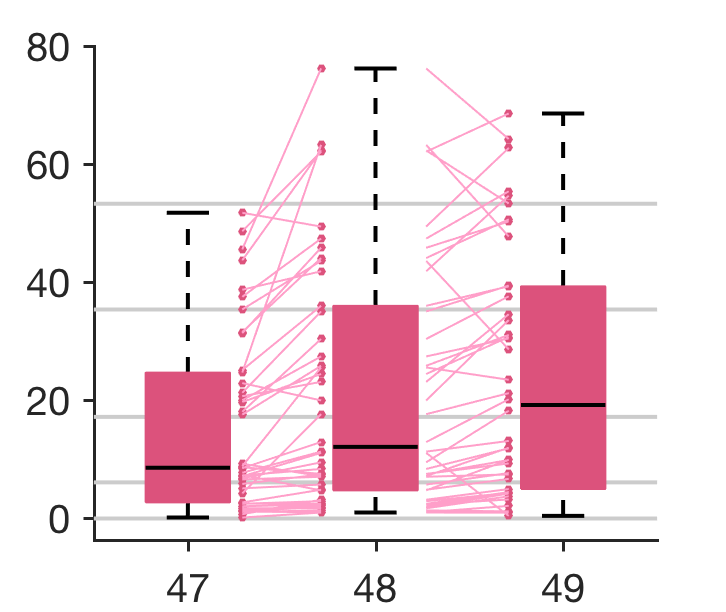


% LMS scale: 
% 0, no sensation; 1.4, barely detectable; 
% 6.1, weak; 17.2, moderate; 35.4, strong; 
% 53.3, very strong; 100, strongest imaginable sensation

create_figure('plot');
set(gcf, 'Position', [1   511   253   194]);

data = [pl.rating_int{1} pl.rating_int{2} pl.rating_int{3}]*100;

cols = [0.8627    0.3216    0.4863
    0.9216    0.6078    0.5608];

cols_dot = [0.8627    0.3216    0.4863];
cols_line = [0.8627    0.3216    0.4863]+.3;
cols_line(cols_line>1)=1;

close all;

anchors = [0 6.1 17.2 35.4 53.3];
boxplot_wani_2016(data, 'color', repmat(cols(1,:),3,1), 'linewidth', 2, 'boxlinewidth', 1, ...
    'refline', anchors, 'reflinestyle', '-', 'reflinecolor', [.8 .8 .8], 'mediancolor', 'k');%,...
    %'boxlinecolor', repmat([0.4660    0.6740    0.1880], 3,1));
% set(gcf, 'position',  [1   512   268   194]);
set(gcf, 'position', [ 1   399   363   306]);
set(gca, 'fontsize', 20, 'xlim', [0.5 3.5], 'linewidth', 1.5, 'ticklength', [.02 .02], 'xticklabel', 47:49);

xdot{1} = ones(42,1)*1+.29;
xdot{2} = ones(42,1)*2-.29;
xdot{3} = ones(42,1)*2+.27;
xdot{4} = ones(42,1)*3-.29;

scatter(xdot{1}, data(:,1), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{2}, data(:,2), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
% scatter(xdot{3}, data(:,2), 15, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{4}, data(:,3), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);

h1 = line([xdot{1} xdot{2}]', data(:,1:2)', 'color', cols_line, 'linewidth', 1);
h2 = line([xdot{3} xdot{4}]', data(:,2:3)', 'color', cols_line, 'linewidth', 1);
% for i = 1:48, h1(i).Color(4) = .5; h2(i).Color(4) = .8; end

savename = fullfile(figdir, 'Study2_pain_ratings.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## plot together

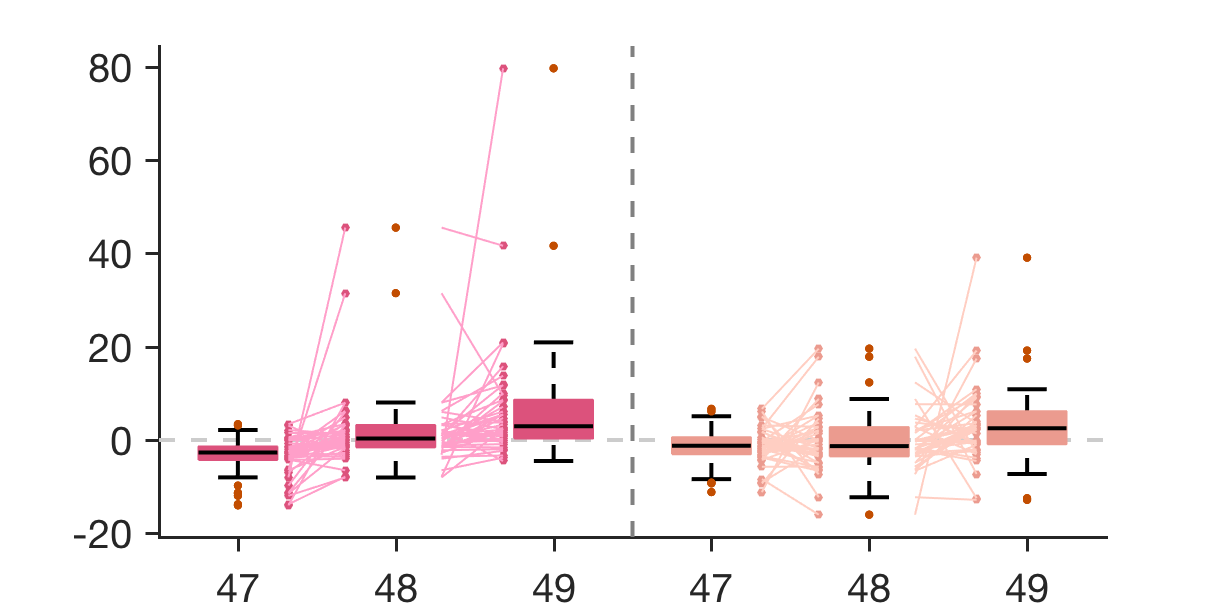

data = [cat(2,pl.test_scr_int{:}) cat(2,pl.test_partner{:})];
% cols = [0.9922    0.7333    0.5176
%     0.9882    0.5529    0.3490
%     0.9373    0.3961    0.2824];
% 
% cols_dot = [0.9922    0.7314    0.5196];
% cols_line = [0.9922    0.8314    0.6196];
% 
cols = [0.8627    0.3216    0.4863
    0.9216    0.6078    0.5608];

cols_dot = cols;
cols_line = [cols(1,:)+.3;cols(2,:)+.2];
cols_line(cols_line>1)=1;

close all;

boxplot_wani_2016(data, 'color', [repmat(cols(1,:),3,1); repmat(cols(2,:),3,1)], 'linewidth', 2, 'boxlinewidth', 1, ...
    'refline', 0, 'reflinestyle', '--', 'reflinecolor', [.8 .8 .8], 'mediancolor', 'k');
set(gcf, 'position', [1   399   611   306]);
set(gca, 'fontsize', 20, 'xlim', [0.5 6.5], 'linewidth', 1.5, 'ticklength', [.015 .015], 'xticklabel', 47:49);

xdot{1} = ones(42,1)*1+.32;
xdot{2} = ones(42,1)*2-.32;
xdot{3} = ones(42,1)*2+.29;
xdot{4} = ones(42,1)*3-.32;

xdot{5} = ones(42,1)*4+.32;
xdot{6} = ones(42,1)*5-.32;
xdot{7} = ones(42,1)*5+.29;
xdot{8} = ones(42,1)*6-.32;

scatter(xdot{1}, data(:,1), 20, cols_dot(1,:), 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{2}, data(:,2), 20, cols_dot(1,:), 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{4}, data(:,3), 20, cols_dot(1,:), 'filled'); %, 'MarkerFaceAlpha', .5);

scatter(xdot{5}, data(:,4), 20, cols_dot(2,:), 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{6}, data(:,5), 20, cols_dot(2,:), 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{8}, data(:,6), 20, cols_dot(2,:), 'filled'); %, 'MarkerFaceAlpha', .5);

h1 = line([xdot{1} xdot{2}]', data(:,1:2)', 'color', cols_line(1,:), 'linewidth', 1);
h2 = line([xdot{3} xdot{4}]', data(:,2:3)', 'color', cols_line(1,:), 'linewidth', 1);

h1 = line([xdot{5} xdot{6}]', data(:,4:5)', 'color', cols_line(2,:), 'linewidth', 1);
h2 = line([xdot{7} xdot{8}]', data(:,5:6)', 'color', cols_line(2,:), 'linewidth', 1);
% for i = 1:48, h1(i).Color(4) = .5; h2(i).Color(4) = .8; end

ylim_main = get(gca, 'ylim');
line([3.5 3.5], ylim_main, 'color', [.5 .5 .5], 'linewidth', 2, 'linestyle', '--');

savename = fullfile(figdir, 'Study2_predicted_pain_SCR.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## roc

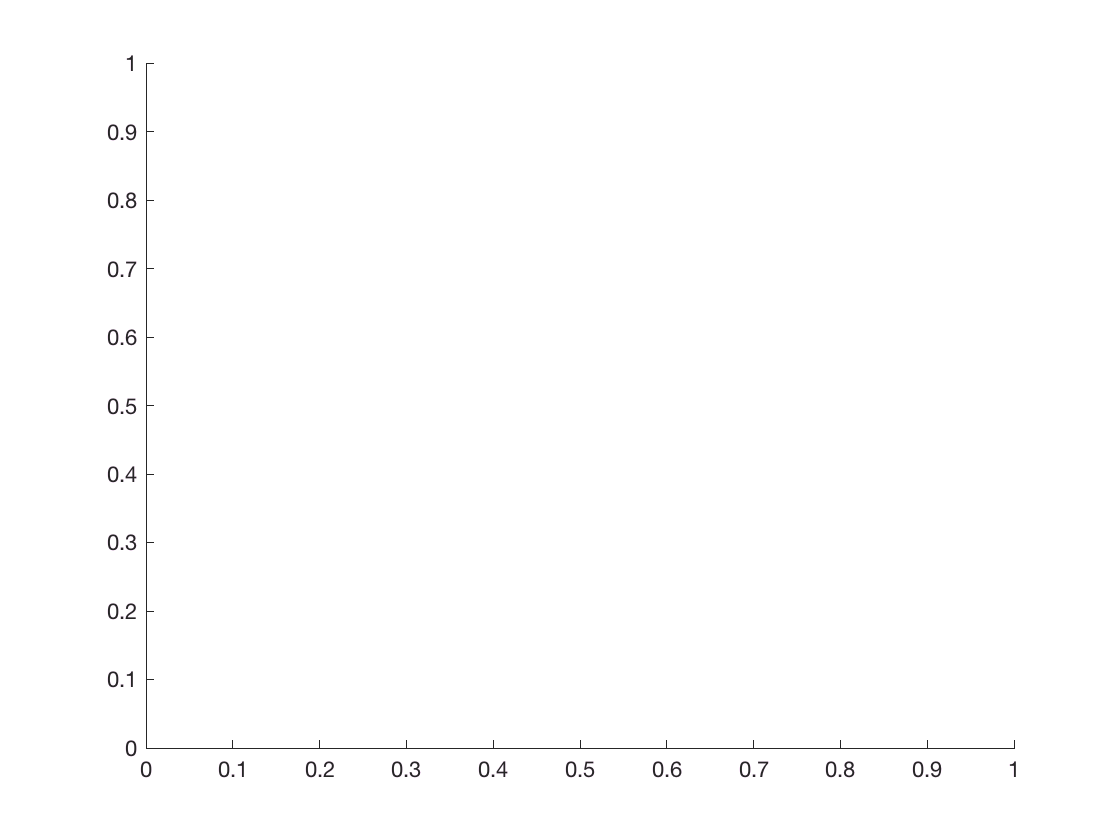

close all;

contrast = [1 3; 1 2; 2 3];
clear h1 h2 h3;

for i = 1:3
    h1{i} = roc_plot([pl.test_scr_int{contrast(i,1)};pl.test_scr_int{contrast(i,2)}], [false(42,1);true(42,1)], 'twochoice', 'nooutput', 'noplot');
end
    
for i = 1:3
    h2{i} = roc_plot([pl.test_partner{contrast(i,1)};pl.test_partner{contrast(i,2)}], [false(42,1);true(42,1)], 'twochoice', 'nooutput', 'noplot');
end

for i = 1:3
    h3{i} = roc_plot([pl.rating_int{contrast(i,1)};pl.rating_int{contrast(i,2)}], [false(42,1);true(42,1)], 'twochoice', 'nooutput', 'noplot');
end

con_s = {'49 vs. 47', '48 vs. 47', '49 vs. 48'};
for i = [1 3 2]
    fprintf('\nSCR rating: for %s, acc = %.3f +- %.3f, p = %.4f', con_s{i}, h3{i}.accuracy, h3{i}.accuracy_se, h3{i}.accuracy_p);
    fprintf('\nSCR main: for %s, acc = %.3f +- %.3f, p = %.4f', con_s{i},h1{i}.accuracy, h1{i}.accuracy_se, h1{i}.accuracy_p);
    fprintf('\nSCR partner: for %s, acc = %.3f +- %.3f, p = %.4f',con_s{i}, h2{i}.accuracy, h2{i}.accuracy_se, h2{i}.accuracy_p);
    disp(' ');
end


SCR rating: for 49 vs. 47, acc = 0.952 +- 0.033, p = 0.0000


SCR main: for 49 vs. 47, acc = 0.929 +- 0.040, p = 0.0000


SCR partner: for 49 vs. 47, acc = 0.714 +- 0.070, p = 0.0079


SCR rating: for 49 vs. 48, acc = 0.810 +- 0.061, p = 0.0001


SCR main: for 49 vs. 48, acc = 0.738 +- 0.068, p = 0.0029


SCR partner: for 49 vs. 48, acc = 0.667 +- 0.073, p = 0.0436


SCR rating: for 48 vs. 47, acc = 0.810 +- 0.061, p = 0.0001


SCR main: for 48 vs. 47, acc = 0.810 +- 0.061, p = 0.0001


SCR partner: for 48 vs. 47, acc = 0.500 +- 0.077, p = 1.0000

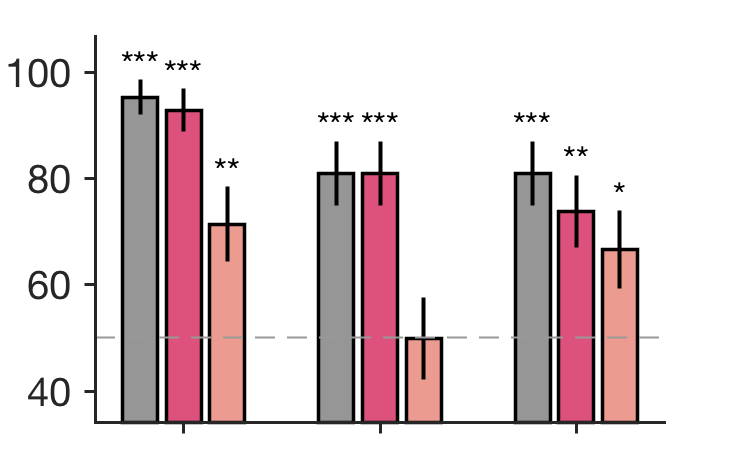



y = [h3{1}.accuracy h1{1}.accuracy h2{1}.accuracy;
    h3{2}.accuracy h1{2}.accuracy h2{2}.accuracy;
    h3{3}.accuracy h1{3}.accuracy h2{3}.accuracy]*100;

e = [h3{1}.accuracy_se h1{1}.accuracy_se h2{1}.accuracy_se;
    h3{2}.accuracy_se h1{2}.accuracy_se h2{2}.accuracy_se;
    h3{3}.accuracy_se h1{3}.accuracy_se h2{3}.accuracy_se]*100;

p = [h3{1}.accuracy_p h1{1}.accuracy_p h2{1}.accuracy_p;
    h3{2}.accuracy_p h1{2}.accuracy_p h2{2}.accuracy_p;
    h3{3}.accuracy_p h1{3}.accuracy_p h2{3}.accuracy_p]; 

cols = [150 150 150;
    220 82 124;
    235 155 143]/255;

h = bar_wani_2016(y, e, .8,  'errbar_width', 0, 'ast', p, 'colors', cols, 'ast_adj_y_pos', .2);
line(get(gca, 'xlim'), [50 50], 'color', [.6 .6 .6], 'linestyle', '--', 'linewidth', 1);
xtickbar = get(gca, 'XTick');
set(gca, 'ticklength', [.02 .02], 'xtick', xtickbar([2 5 8]), 'linewidth', 1.5);
set(gcf, 'position', [1   463   367   237]);

savename = fullfile(figdir, 'Study2_accuracy_bar.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);